# Coherence Analysis

## Use of the function for coherence analysis

Estimation of intermuscular coherence using the NeuroSpec Toolbox. 

All associated code and calculations are within the function file "calculate_coherence.m".

**NOTE: IN ORDER TO RUN THIS CODE, YOU MUST DOWNLOAD THE NEUROSPEC20 TOOLBOX.**

- This can be downloaded from: [https://github.com/dmhalliday/NeuroSpec/blob/master/neurospec20.zip](https://github.com/dmhalliday/NeuroSpec/blob/master/neurospec20.zip) 

- Once downloaded and unzipped, place the entire folder within the folder "+coherence"

- ALL RIGHTS TO DAVID HALLIDAY. David Halliday et al. have allowed the use of this toolbox under a GNU general public license.

NOTE: To use this code, ensure your currrent path is in the outermost folder of this repository.

clc, clear

[coherence_data, inputdata, cov, pooled_coherence, comparison_of_coherence] = coherence.data_analysis.calculate_coherence();


Processing P3 Coherence:
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.

Processing P4 Coherence:
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment length: 0.46085 sec,  Resolution: 2.1699 Hz.
Segments: 8, Segment len

Plot the outputs using the NeuroSpec Toolbox's plotting function

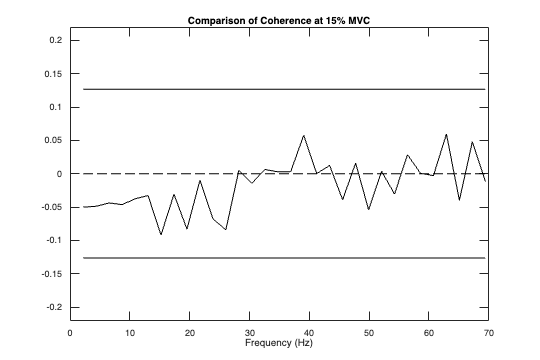

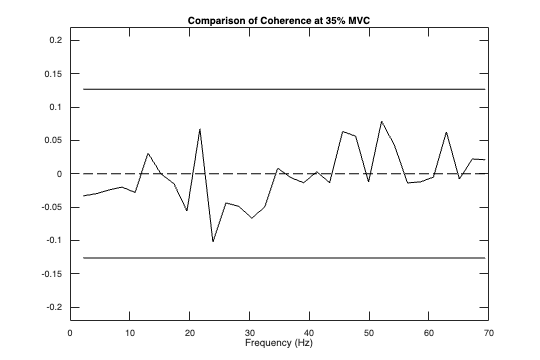

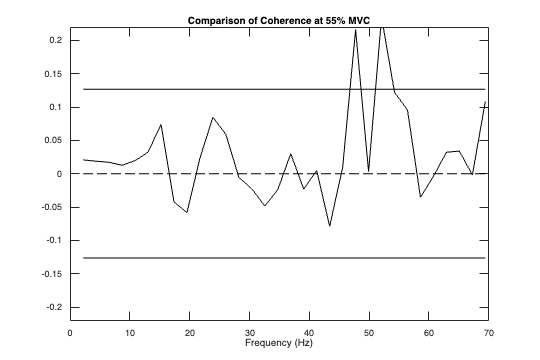

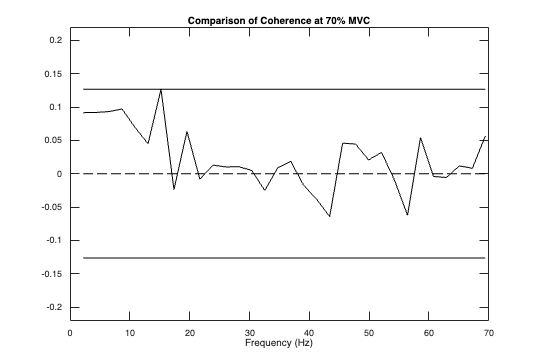

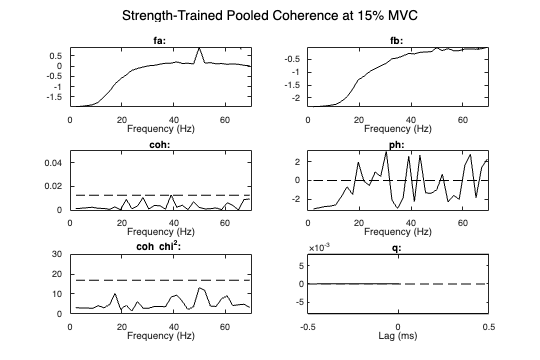

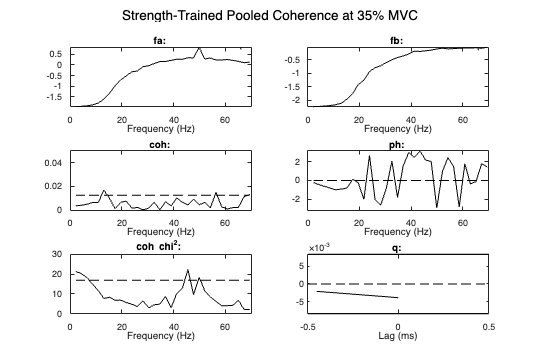

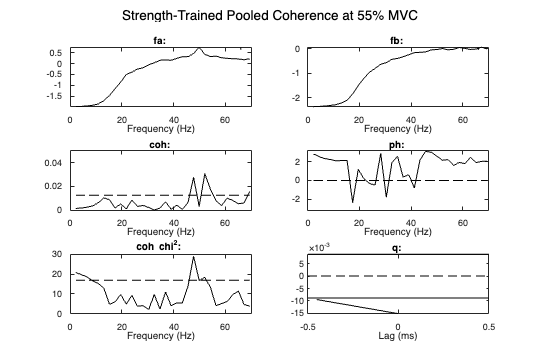

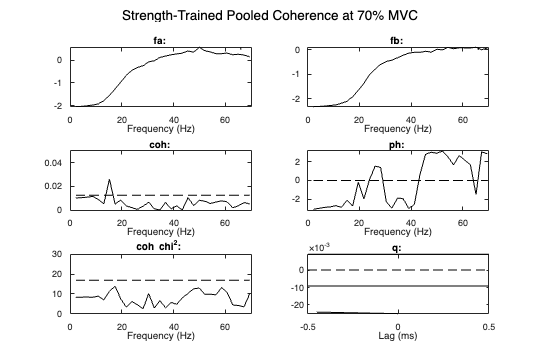

coherence.data_analysis.neurospec_plot_coherence(pooled_coherence, comparison_of_coherence);

Organise the data to export to R for plotting using ggplot:

[pooled_coherence_for_R, comparison_of_coherence_for_R] = coherence.data_analysis.plotting_data_for_R(pooled_coherence, comparison_of_coherence)

pooled_coherence_for_R = 512×17 table
     freq     strength_coh_15    strength_ci_15    strength_coh_35    strength_ci_35    strength_coh_55    strength_ci_55    strength_coh_70    strength_ci_70    dexterity_coh_15    dexterity_ci_15    dexterity_coh_35    dexterity_ci_35    dexterity_coh_55    dexterity_ci_55    dexterity_coh_70    dexterity_ci_70
    ______    _______________    ______________    _______________    ______________    _______________    ______________    _______________    ______________    ________________    

comparison_of_coherence_for_R = 512×9 table
     freq     compcoh_15     ci_15     compcoh_35      ci_35     compcoh_55     ci_55     compcoh_70     ci_70 
    ______    __________    _______    ___________    _______    __________    _______    __________    _______

    2.1699     -0.050155    0.12652      -0.033279    0.12652      0.020764    0.12652      0.091546    0.12652
    4.3398     -0.048897    0.12652      -0.030059    0.12652      0.018696    0.12652      0.091868    0.12652
    6.5098     -0.043857    0.12652      -0.024313    0.12652      0.017114    0.12652      0.093198    0.12652
    8.6797     -0.046387    0.12652      -0.020076    0.12652      0.012597    0.12652   

Save the data ready for plotting in R.

writetable(pooled_coherence_for_R, fullfile('+coherence','+plotting','pooled_coherence_data.csv'));
writetable(comparison_of_coherence_for_R, fullfile('+coherence','+plotting','comparison_of_coherence_data.csv'));